## ExergyAnalysis 

Perform exergy analysis of a data model for a specific system operating state.

### Description:

Analyzes a thermoeconomic data model using the Second Law of Thermodynamics, to calculate the irreversibilities and efficiencies for all processes of the model. This analysis step quantifies the energy quality degradation and process performance.

This function required a data model, including the exergy values for all system flows to calculate:

- The exergy of fuel and products of each process.

- The irreversibilities (exergy destruction)

- The unit consumption and exergetic efficiency

- The Fuel-Product tables showing the processes relationships

### Syntax:

`    res = ExergyAnalysis(data);`

`    res = ExergyAnalysis(data, Name, Value)`

###  Input Arguments:

     `data` - Data model containing plant structure and thermodynamic states

         `cDataModel object`

###  Name-Value Arguments:

      `State` - Name of the operating state to analyze

          `char array` (default value: first state in data model)

      `Show` - Display exergy analysis results in console

          `logical `(default value: false)

      `SaveAs` - Save results to an external file

          `char array | string` (default: empty)

          It saves the result tables to a file, Format is determined by file extension.

          Supported formats are : XLSX, CSV, HTML, LaTex, Markdown and MAT

### Output Arguments:

`    res` - cResultInfo object containig exergy analysis results 

       ** ResultInfo:**

`        cExergyModel` (cType.ResultId.THERMOECONOMIC_STATE)

        **Generated Tables**:

`        eflows` - Exergy values for all flows.

`        estreams` - Exergy values for productive groups (streams)

`        eprocesses` - Exergy balance for each process.

`        tfp `- Fuel-Product table

### Workflow Integration:

        1. ReadDataModel() - Load plant data with thermodynamic states

        2. ProductiveStructure() - Verify topology (optional)

        3. **ExergyAnalysis()** - Calculate exergy (this function)

        4. ThermoeconomicAnalysis() - Calculate costs based on exergy

        5. ThermoeconomicDiagnosis() - Compare states and detect malfunctions

### Error Handling:

Returns invalid `cResultInfo` object if:

- Input is not a valid cDataModel object

- Specified state does not exist in the data model

- Exergy data is missing or invalid for the state

- Exergy balance calculations fail

.

### Examples:

    **Example 1: **Get the results of the exergy analysis of CGAM model (default state)

filename = getExamplesFilename('cgam','cgam_model.json');
data = ReadDataModel(filename);
res = ExergyAnalysis(data)

res =   cResultInfo with properties:

          Tables: [1×1 struct]
      NrOfTables: 4
            Info: [1×1 cExergyModel]
         ClassId: 1
        ResultId: 2
      ResultName: 'Exergy Analysis'
       ModelName: 'cgam_model'
           State: 'REF'
          Sample: ''
    DefaultGraph: 'tfp'
          status: 1
        objectId: 1749606800


if isValid(res)
    fprintf('Exergy Analysis completed for state %s\n', res.State);
end     

Exergy Analysis completed for state REF


    **Example 2:** Calculate an specific state `(ETG87) `and show the results

disp(data.StateNames);

    {'REF'}    {'T1180'}    {'ETG87'}    {'ECMP84'}    {'RP8'}    {'PINCH15'}    {'CGAMR'}    {'noAPH'}



res = ExergyAnalysis(data, 'State', 'ETG87','Show',true);


Flows Exergy Table - ETG87

Key  From     To              B(MW)
————————————————————————————————————
NG   ENV_R1   COMB_F1        73.600
B1   ENV_R2   CMP_P1          0.000
B2   CMP_P1   APH_P1         29.337
B3   APH_P1   COMB_F1        51.926
B4   COMB_P1  TRB_F1        104.971
B5   TRB_F1   APH_F1         40.230
B6   APH_F1   HRSG_F1        15.213
B7   HRSG_F1  STCK_F1         2.156
WC   TRB_P1   CMP_F1         31.849
WN   TRB_P1   ENV_O1         30.000
QV   HRSG_P1  ENV_O2          9.591
QG   STCK_P1  ENV_W1          2.156


Productive Groups Exergy Table - ETG87

Key             E(MW)      ET(MW)
——————————————————————————————————
COMB_F1       125.526     125.526
COMB_P1       104.971     104.971
CMP_F1         31.849      31.849
CMP_P1         29.337      29.337
TRB_F1         64.741     104.971
TRB_P1         61.849      61.849
APH_F1         25.017      40.230
APH_P1         22.589      51.926
HRSG_F1        13.057      15.213
HRSG_P1         9.591       9.591
STCK_F1        

    **Example 3:** Export the results to Excel

folderName=fileparts(filename);
outputfile=fullfile(folderName,'cgam_ECMP84.xlsx');
res = ExergyAnalysis(data, 'State','ECM84', 'SaveAs', outputfile);

    ** Example 4:** List the available result tables and show specific results

ListResultTables(res);

INFO: cMessageLogger. Exergy Analysis is saved in file C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_ECMP84.xlsx



Exergy Analysis - Table Index

 Key          Description                      Graph  
————————————————————————————————————————————————————————
 eflows       Flows Exergy Table               false  
 estreams     Productive Groups Exergy Table   false  
 eprocesses   Processes Exergy Table           false  
 tfp          FP Table                         true   




Processes Exergy Table - ETG87

Key          F(MW)       P(MW)       I(MW)       k(J/J)      η (%)
———————————————————————————————————————————————————————————————————
COMB       125.526     104.971      20.555       1.1958      83.62
CMP         31.849      29.337       2.512       1.0856      92.11
TRB         64.741      61.849       2.892       1.0468      95.53
APH         25.017      22.589       2.428       1.1075      90.29
HRSG        13.057       9.591       3.466       1.3614      73.45
STCK         2.156       2.156       0.000       1.0000     100.00
ENV         73.600      39.591      34.009       1.8590      53.79



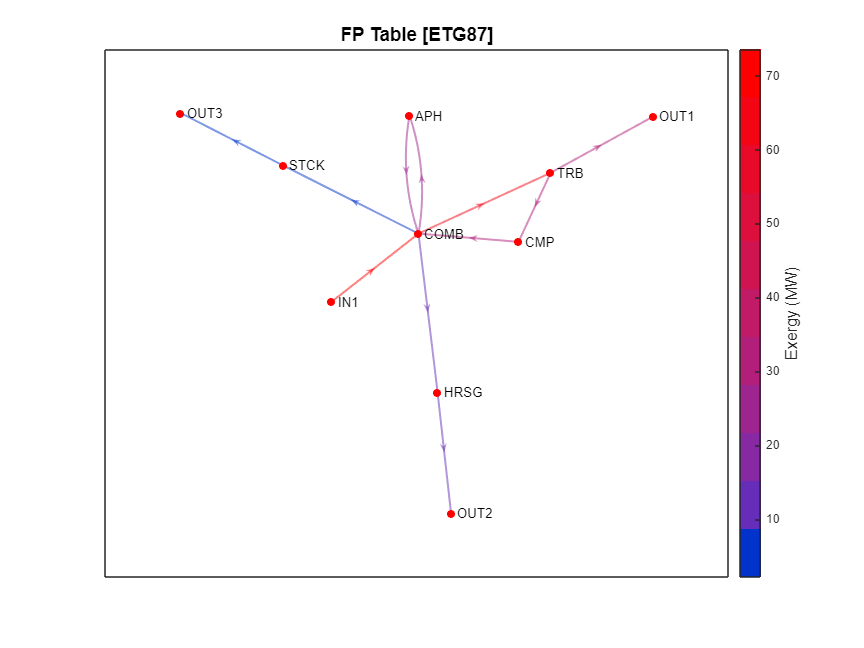

ShowResults(res,'Table','eprocesses');
ShowGraph(res,'Graph','tfp');

### See Also:

[ExergyAnalysisDemo, ](matlab:open('./ExergyAnalysisDemo.mlx'))[ReadDataModel, ](matlab:open('./ReadDataModelDemo.mlx'))[ListResultTables](matlab:open('./TableInfoDemo.mlx'))